clear all;
clc; 
close all;

robot = importrobot("C:\Users\atjensvo\cernbox\Documents\GitHub\MasterThesis\MATLAB\Collision_test.urdf", "DataFormat", "row");
%robot = importrobot("C:\Users\atjensvo\cernbox\Documents\MATLAB\Collision_test_extended.urdf", DataFormat="row");

q_home = [0 0 0 0 0 0 0 0 0];
eeName = "Tool_1";
config = q_home;

Show arm in home position

figure;
show(robot,q_home, Visuals="off", Collisions="on");
hold on

Generate environment

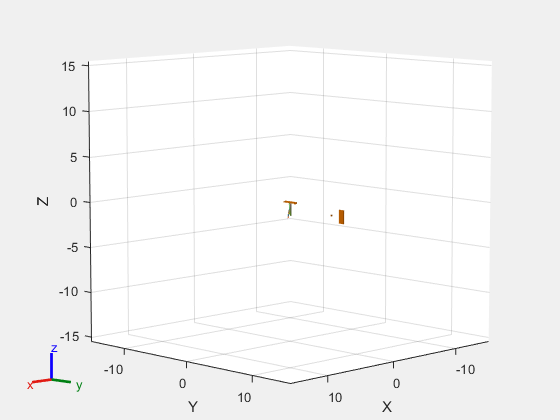

collisionBoxes = { 
    collisionBox(0.278, 1.800, 0.100),   % Wagon Roof
    collisionBox(0.010, 1.800, 0.210),   % Left Wall
    collisionBox(0.010, 0.285, 0.210),   % Right Wall
    collisionBox(0.136, 0.120, 0.168),   % Source Holder
    collisionBox(0.079, 2*0.350, 1.5)    % Electrical obstacle
};

boxPoses = [
     0.000,  0.000,  0.000, 1, 0, 0, 0; 
    -0.152,  0.000, -0.105, 1, 0, 0, 0;
     0.126,  0.900, -0.105, 1, 0, 0, 0; 
    -0.952, 5.400, -0.986, 1, 0, 0, 0;
    -0.952, 6.900, -0.986, 1, 0, 0, 0
];

%% Assign poses and display each collision box
for i = 1:length(collisionBoxes)
    P = trvec2tform(boxPoses(i, 1:3)); 
    R = axang2tform(boxPoses(i, 4:7));
    collisionBoxes{i}.Pose = P * R;
    
    % Display the collision object
    show(collisionBoxes{i});
    hold on;
end